Step 1: Load Dataset

data = readtable("C:\Users\yashw_d6scpoj\Desktop\MFCEOC\smoted_dataset.csv");

Step 2: Remove Non-Numeric Features (src_ip, dst_ip)

data(:, {'src_ip', 'dst_ip'}) = []; % Remove categorical columns

Step 3: Extract Features and Target Variable

X = table2array(data(:, 1:end-1)); % Convert numeric features to matrix
Y = table2array(data(:, end)); % Convert labels to numeric array
Y = grp2idx(Y); % Convert categorical labels to numerical

% Identify zero-variance columns
zeroVarIdx = var(X) == 0;
X(:, zeroVarIdx) = []; % Remove zero-variance columns->Since they donot contribute to any change in the prediction.

Train-test split

cv = cvpartition(Y, 'HoldOut', 0.2);
X_train = X(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X(test(cv), :);
Y_test = Y(test(cv), :);8 

Training and testing Naïve Bayes model

NB_model = fitcnb(X_train, Y_train);%Training

NB_pred = predict(NB_model, X_test);% Predicting on test data


Evaluation

NB_accuracy = sum(NB_pred == Y_test) / length(Y_test) * 100;
disp(['Naïve Bayes Accuracy: ', num2str(NB_accuracy), '%'])

Naïve Bayes Accuracy: 99.4226%


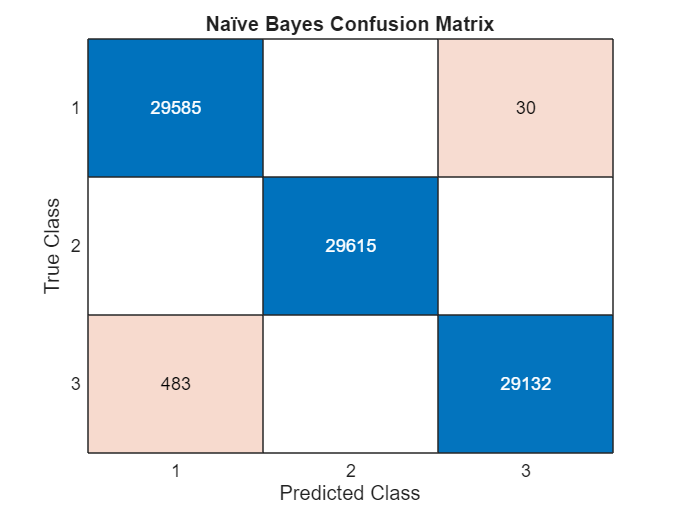


% Confusion Matrix
figure;
confusionchart(Y_test, NB_pred);
title('Naïve Bayes Confusion Matrix');